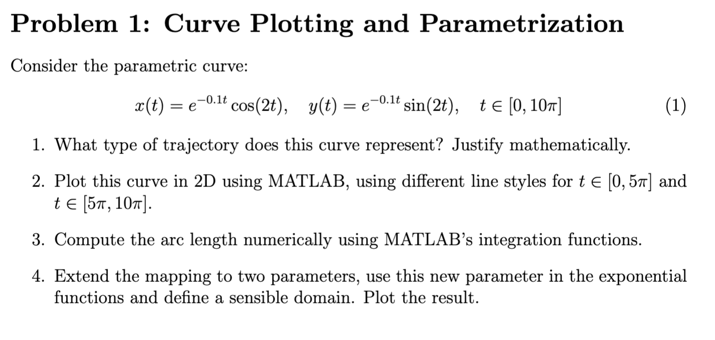

%% Problem 1: Curve Plotting and Parametrization

% Part 1: Mathematical Justification
% The parametric curve represents a spiral that decays exponentially
% because the exponential term (e^(-0.1t)) reduces the amplitude of the 
% cosine and sine functions as t increases.

%% Part 2: Plotting the Curve
% Define the parametric equations and time intervals
t1 = linspace(0, 5*pi, 500); % Interval [0, 5*pi]
t2 = linspace(5*pi, 10*pi, 500); % Interval [5*pi, 10*pi]

x1 = exp(-0.1 * t1) .* cos(2 * t1);
y1 = exp(-0.1 * t1) .* sin(2 * t1);
x2 = exp(-0.1 * t2) .* cos(2 * t2);
y2 = exp(-0.1 * t2) .* sin(2 * t2);

% Plot the curve using different line styles
figure; % Create a new figure
plot(x1, y1, 'r-', 'LineWidth', 1.5); hold on; % Red line for [0, 5*pi]
plot(x2, y2, 'b--', 'LineWidth', 1.5); % Blue dashed line for [5*pi, 10*pi]
xlabel('x(t)');
ylabel('y(t)');
title('Parametric Curve: Decaying Spiral');
legend('t \in [0, 5\pi]', 't \in [5\pi, 10\pi]');
grid on;

%% Part 3: Compute Arc Length Numerically
% Arc length formula: L = integral(sqrt((dx/dt)^2 + (dy/dt)^2)) over t
dx = @(t) -0.1 * exp(-0.1 * t) .* cos(2 * t) - 2 * exp(-0.1 * t) .* sin(2 * t);
dy = @(t) -0.1 * exp(-0.1 * t) .* sin(2 * t) + 2 * exp(-0.1 * t) .* cos(2 * t);
integrand = @(t) sqrt(dx(t).^2 + dy(t).^2);

% Compute the arc length using MATLAB's integral function
arc_length = integral(integrand, 0, 10*pi);
fprintf('The arc length of the curve is approximately %.4f units.\n', arc_length);

The arc length of the curve is approximately 19.1596 units.



%% Part 4: Extend the Mapping to Two Parameters
% Introduce a new parameter z in the exponential function
t = linspace(0, 10*pi, 500); % Reuse the full interval
z = linspace(0.1, 0.5, 200); % Define a new parameter z
[T, Z] = meshgrid(t, z); % Create mesh grid of t and z

% Evaluate parametric equations over the grid
X = exp(-Z .* T) .* cos(2 * T);
Y = exp(-Z .* T) .* sin(2 * T);

% 3D plot of the extended curve
figure; % Create a new figure for the 3D plot
surf(X, Y, Z, 'EdgeColor', 'none'); % Smooth surface without edges
xlabel('x(t, z)');
ylabel('y(t, z)');
zlabel('z');
title('Extended Parametric Curve with Two Parameters');
colormap turbo; % Optional: change color map
colorbar;
grid on;

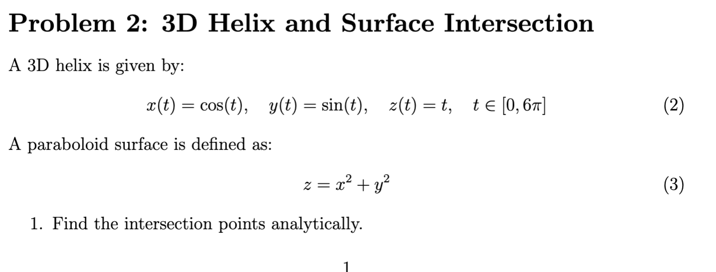

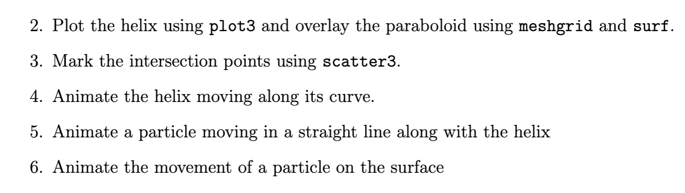

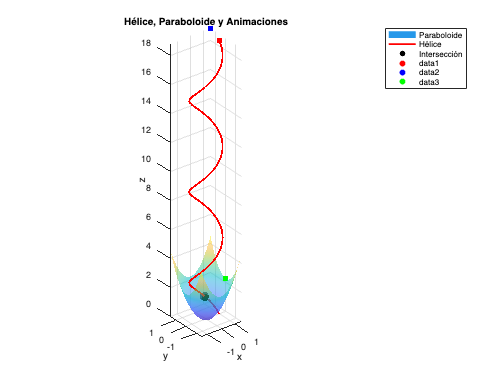

clc;
clear;
close all;

%% Punto 1: Intersección analítica
% Sabemos que: z = t, z = x^2 + y^2 → t = cos^2(t) + sin^2(t) = 1
t_int = 1;
x_int = cos(t_int);
y_int = sin(t_int);
z_int = t_int;

%% Punto 2 y 3: Graficar hélice, paraboloide y punto de intersección
% Hélice
t = linspace(0, 6*pi, 500);
x_helix = cos(t);
y_helix = sin(t);
z_helix = t;

% Paraboloide
[X, Y] = meshgrid(linspace(-1.5, 1.5, 100));
Z = X.^2 + Y.^2;

% Figura base
figure;
hold on;
grid on;
view(3);
axis equal;
xlabel('x'); ylabel('y'); zlabel('z');
title('Hélice, Paraboloide y Animaciones');

% Paraboloide
surf(X, Y, Z, 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% Hélice
plot3(x_helix, y_helix, z_helix, 'r', 'LineWidth', 2);

% Punto de intersección
scatter3(x_int, y_int, z_int, 100, 'k', 'filled');
legend('Paraboloide', 'Hélice', 'Intersección');

%% Punto 4: Animar partícula moviéndose en la hélice
% Usamos un marcador que recorra los puntos de la hélice
particle1 = plot3(NaN, NaN, NaN, 'ro', 'MarkerFaceColor', 'r');

for i = 1:length(t)
    set(particle1, 'XData', x_helix(i), 'YData', y_helix(i), 'ZData', z_helix(i));
    pause(0.01);
end

%% Punto 5: Animar partícula moviéndose en línea recta junto a la hélice
% Línea recta entre (1.5, 1.5, 0) y (1.5, 1.5, 6*pi)
z_line = linspace(0, 6*pi, 500);
x_line = ones(size(z_line)) * 1.5;
y_line = ones(size(z_line)) * 1.5;
particle2 = plot3(NaN, NaN, NaN, 'bo', 'MarkerFaceColor', 'b');

for i = 1:length(z_line)
    set(particle2, 'XData', x_line(i), 'YData', y_line(i), 'ZData', z_line(i));
    pause(0.01);
end

%% Punto 6: Animar partícula moviéndose sobre la superficie del paraboloide
% Movimiento en espiral sobre el paraboloide: r(t), θ(t)
theta = linspace(0, 4*pi, 400);
r = linspace(0, 1.5, 400);
x_surf = r .* cos(theta);
y_surf = r .* sin(theta);
z_surf = x_surf.^2 + y_surf.^2;
particle3 = plot3(NaN, NaN, NaN, 'go', 'MarkerFaceColor', 'g');

for i = 1:length(theta)
    set(particle3, 'XData', x_surf(i), 'YData', y_surf(i), 'ZData', z_surf(i));
    pause(0.01);
end